num = 750;
den = [1 36 205 750];

G0 = tf(num, den);
[p, z] = pzmap(G0)

p =  -30.0000 + 0.0000i
  -3.0000 + 4.0000i
  -3.0000 - 4.0000i



z =

  0×1 empty double column vector



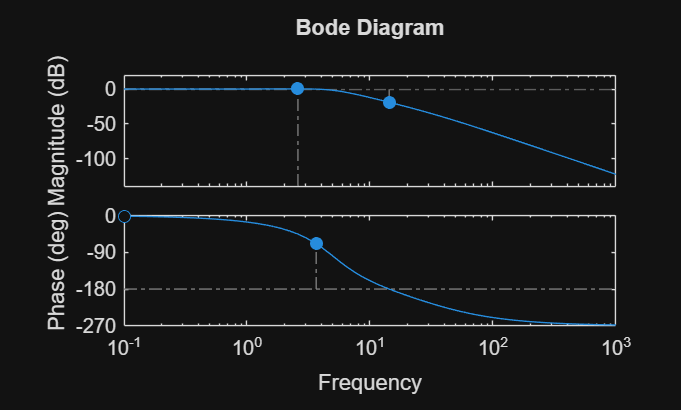


num_r = 750 / 30;
den_r = [1 6 25];

G0r = tf(num_r, den_r);

bode(G0)

[mag, ph, w] = bode(G0);
[Mr, k] = max(mag)

Mr = 1.0377

k = 23

wr = w(k)

wr = 2.5971


n=1

n = 1

while 20*log10(mag(n)) > -3
    n = n+1;
end
banda = w(n)

banda = 6.5860

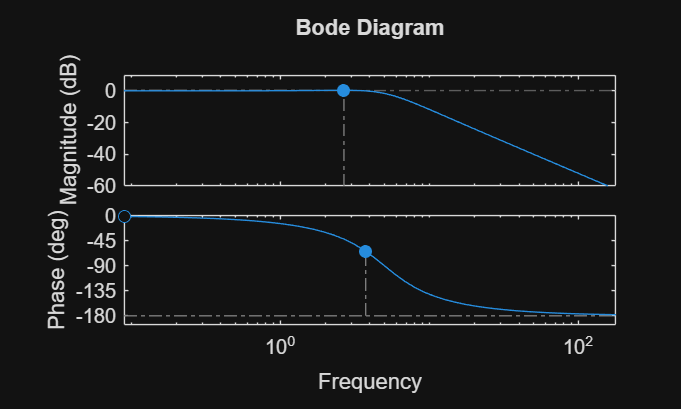


bode(G0r)

[mag, ph, w] = bode(G0r);
[Mr, k] = max(mag)

Mr = 1.0416

k = 23

wr = w(k)

wr = 2.6738


n=1

n = 1

while 20*log10(mag(n)) > -3
    n = n+1;
end
banda = w(n)

banda = 5.8469